# lab3 sectin2

## q2

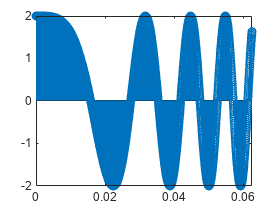

figure(3)
f1 = 0;
n1 = 0;
mue = 2000;
Fs = 32*10^3;
n2 = 8*Fs;
[tvec, cnTs] = sample_chirpgen(f1, 2, Fs, 0, n1, n2, mue);
stem(tvec(1:2000), cnTs(1:2000));

soundsc(cnTs, Fs)
pause(8);


## q3

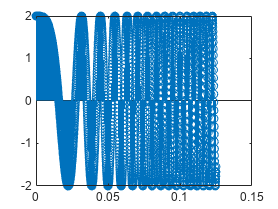

figure(4)
Fs = 16*10^3;
n2 = 8*Fs;
[tvec, cnTs] = sample_chirpgen(f1, 2, Fs, 0, n1, n2, mue);
stem(tvec(1:2000), cnTs(1:2000));

soundsc(cnTs, Fs)
pause(8);


## q4

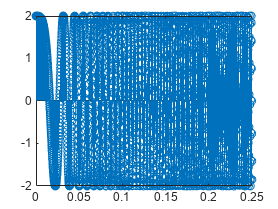

figure(5)
Fs = 8*10^3;
n2 = 8*Fs;
[tvec, cnTs] = sample_chirpgen(f1, 2, Fs, 0, n1, n2, mue);
stem(tvec(1:2000), cnTs(1:2000));

soundsc(cnTs, Fs)
pause(8);


## q5

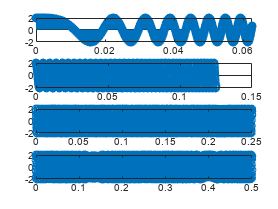

figure(5)
f1 = [0 200 400 600];
Fs = [32 16 8 4].*10^3;
mue = [4000 2000 1000 500];
for i = 1:4
    n2=8*Fs(i);
    subplot(4,1,i)
    [tvec, cnTs] = sample_chirpgen(f1(i), 2, Fs(i), 0, n1, n2, mue(i));
    stem(tvec(1:2000), cnTs(1:2000));
    soundsc(cnTs, Fs(i));
    pause(8);
end